## Diagramma Universale Rete Anticipatrice.

Disegnare in MATLAB i diagrammi universali della funzione anticipatrice, come mostrati nella lezione.

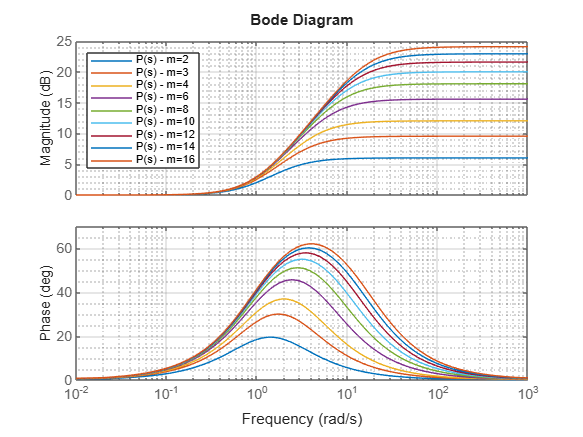

m = [2,3,4,6,8,10,12,14,16];
num = [1 1];

for index = 1:length(m)
    den = [1/m(index) 1]; % Si ricalcola il denominatore in base al valore di m.
    
    P_s = tf(num,den); % Si ricalcola la FdT in base al valore di m.
    
    bode(P_s)
    grid on
    grid minor
    hold on
end

hold off

legend("P(s) - m=2","P(s) - m=3","P(s) - m=4","P(s) - m=6","P(s) - m=8", ...
       "P(s) - m=10","P(s) - m=12","P(s) - m=14","P(s) - m=16");
legend("Location","northwest");